**SPFI evaluation for single EV/LNP capture**

clear all; clc;

%add path to the EV-localization scripts
%also requires bfmatlab toolbox from Open Microscopy Environment
%(https://www.openmicroscopy.org/bio-formats/downloads/)
addpath(genpath(pwd));
params = struct();

%filepath to the nd2 files
params.fpath = '/Users/awallucks/Downloads/SPFI_A431_CD63-GFP/';
mkdir([params.fpath, 'plots']);

%Vesicle incubation timepoints, typically 2 but can be arbitrary large
params.num_timepoints = 2;

%number of FOVs that should be read into h5 file
params.num_FOVs = 12;

%FOV indices that are used in the analysis (h5 contains all FOV)
params.valid_fovs = 1:params.num_FOVs;
%remove invalid FOVs if necessary (overexposed etc)
%params.valid_fovs() = [];                  

%names of OC that were taken. Order determines how they will be sorted into the h5 file
%iSCAT channels must come first in order of wavelength
%iSCAT OC names must match highres iSCAT OC exactly and be contained in flatfield OC 
params.OC_names = {'iSCAT440nm', 'iSCAT740nm', 'AF470'};
params.channel_wavelengths = [440, 740, 510]*1e-9;

%define what the channels are used for
params.iscat_chans = [1, 1, 0];           %iSCAT channels           
params.fluo_chans =  [0, 0, 1];           %fluorescence labels

%define if iSCAT channels are stitched
params.twocolor_iscat = true;

%define which channels shoul be corrected for chromatic aberrations
%channel2 (740 nm iSCAT) needs to be corrected for correct cotrast stitching
%channel3 (GFP) has no correction necessary as it is spectrally close to 440 nm iSCAT
%note that correction maps from full frame datasets without ROI give better
%results, especially around the image borders
params.chans_to_correct = [2];

%Thresholds on iSCAT contrasts in third root scaling
params.iscat_thresh = 0.12;

%Define the channels containing fluorescent labels
params.lbl_names = {'GFP'};         %label or target name for plots
params.lbl_tps = [2];               %timepoint(s) in which they should be evaluated (each label has one)
params.lbl_threshs = [2.2];           %threshold(s) (note square root scaling in plots by default)

%additional parameters that are rarely changed
params = initialize_low_level_params(params);

Read in all the nd2 files. 

read_nd2_files(params);

Chan 2before alignment:

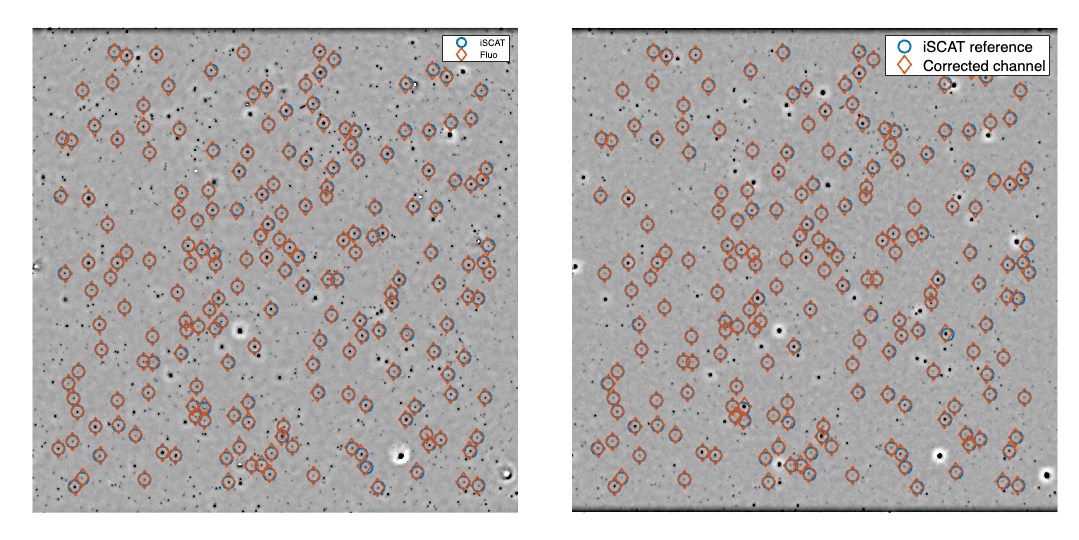

Chan 2 alignment map:

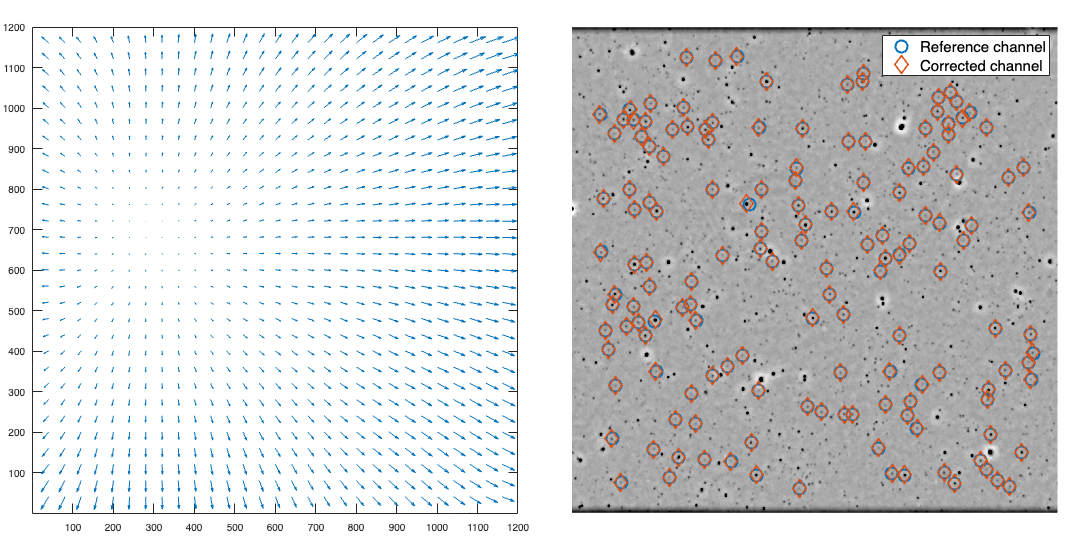


%correct chromatic aberrations
correct_for_chromatic_abberation(params, 'load_abberation_correction', false);

Align FOVs between timepoints

Image diplacement QC: check for outliers

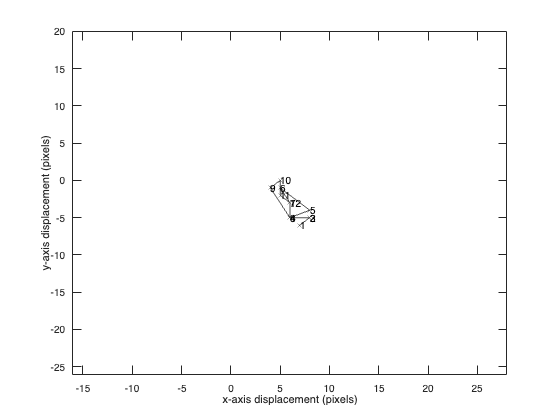

params = align_FOVs_between_timepoints(params);

iSCAT candidate spot localization

Timepoint 1 crud detection


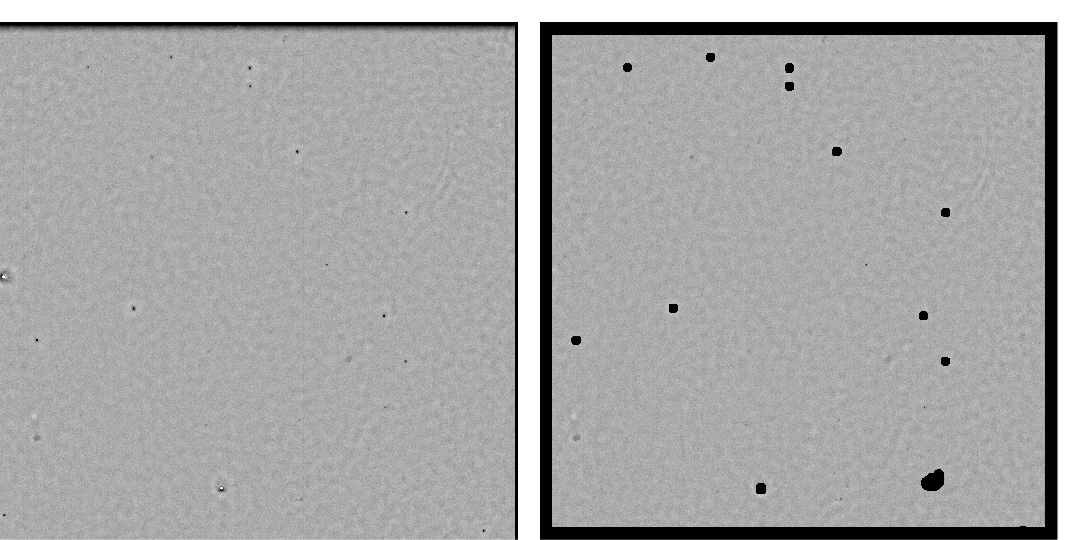

Timepoint 2 crud detection

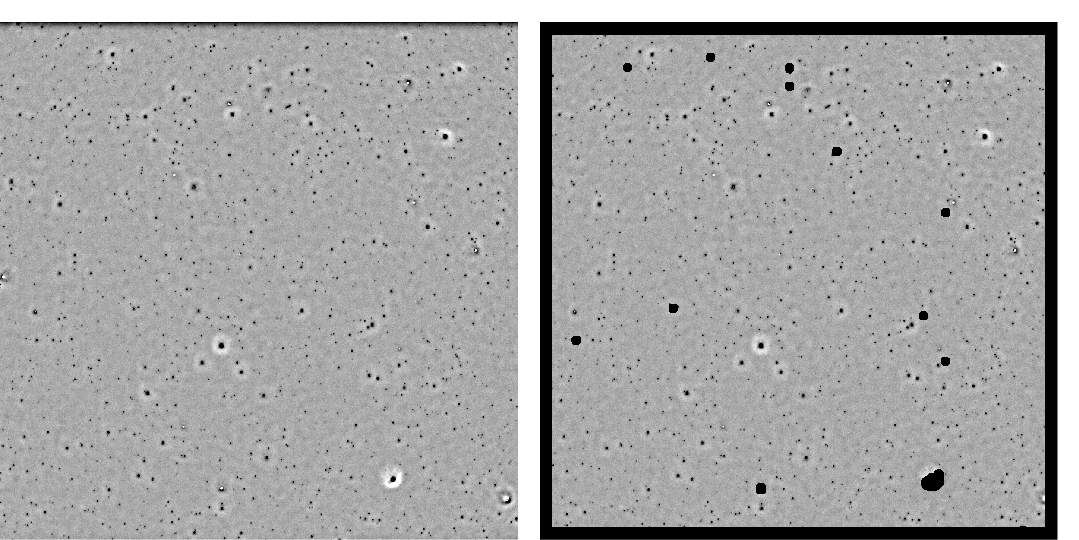

localize_candidate_spots(params);

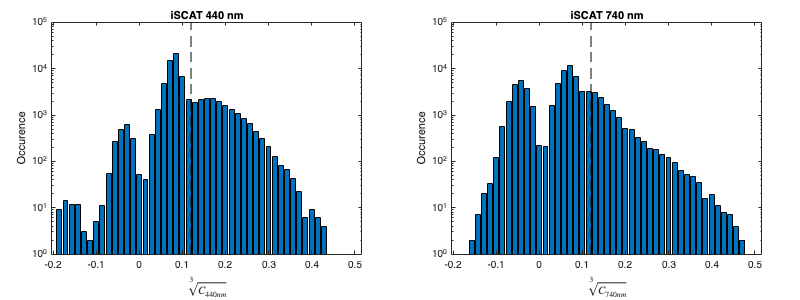

plot_candidate_spot_histograms(params);

Measure the fluorescence intensities for all the iSCAT candidate spots, both labels and DEI data

chan 1

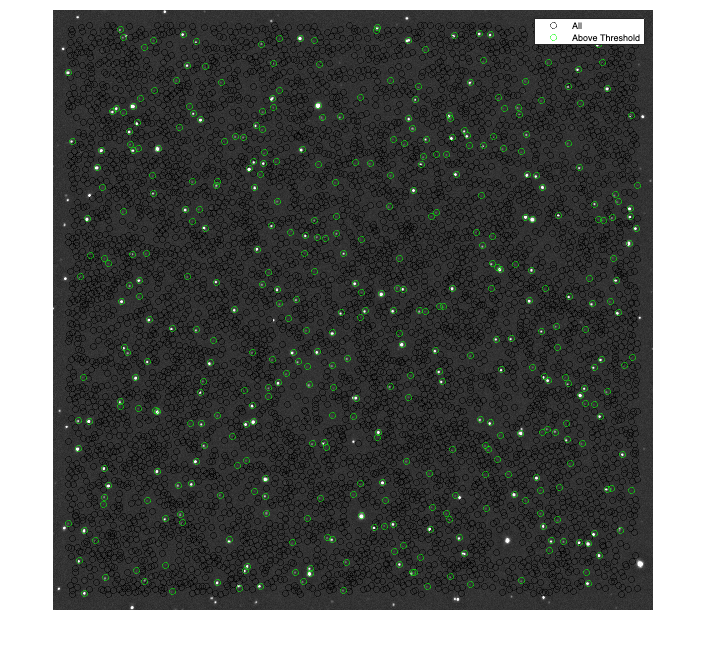

measure_fluorescence_intensities(params);

Stitch iSCAT channels together if requested

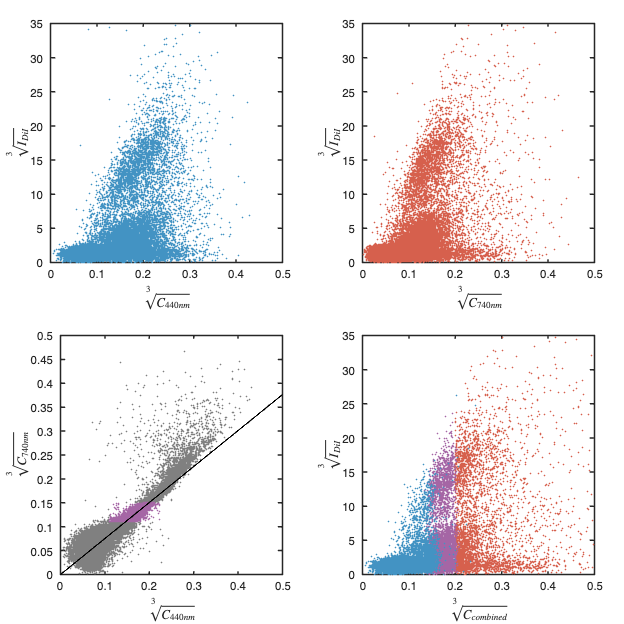

stitch_iSCAT_measurements(params);

Prepare SPFI scatterplots: Combine all candidate spot data into single big table called spfi

initialize_spfi_data(params);

SPFI channel indices:
01 -> SP
02 -> iSCAT440
03 -> iSCAT740
04 -> GFP


Plot SPFI data using the channel numbers from the cell above

<'identify_spots', true> can be used to select a group of points and mark the in the h5 file for visualization

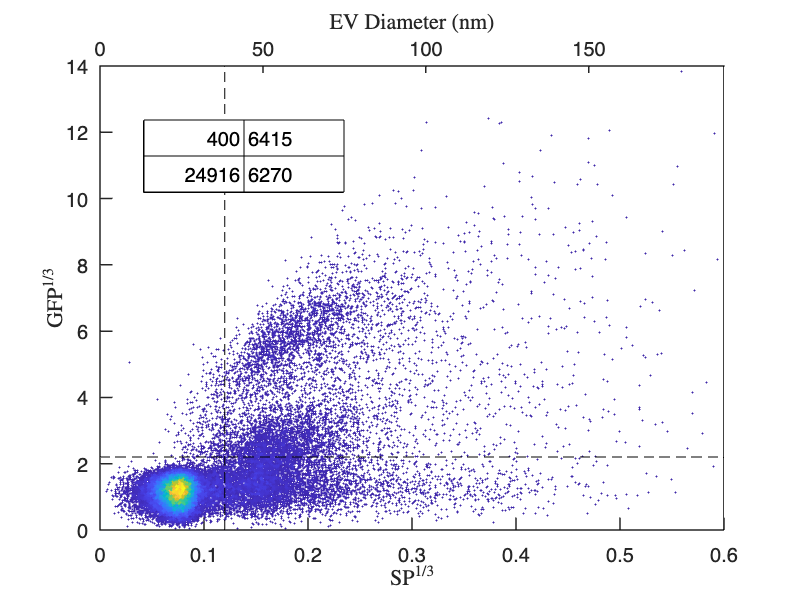

xl = [0, 0.6];
yl = [0, 14];

spfi_plot(params, 1, 4, xl, yl, 'calibrate_xaxis', true);

Example how to plot the data for visual inspection

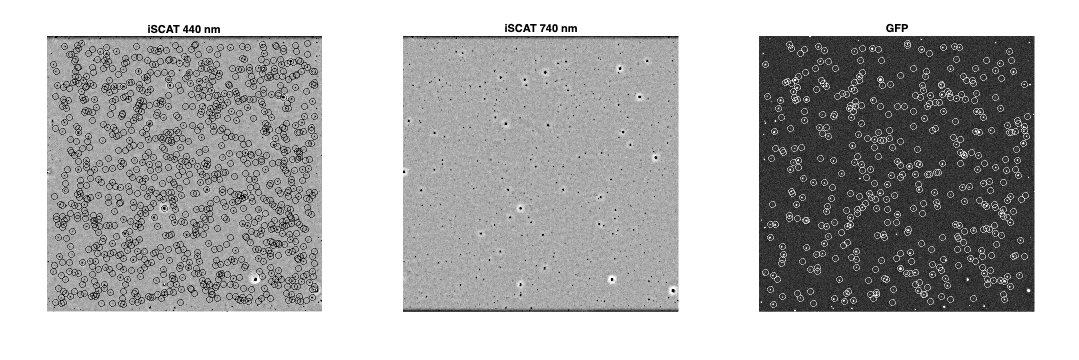

timepoint = 2;
FOV = 1;
chan1 = h5r(params.h5_file, timepoint, 1, FOV);
[posx1, posy1] = h5r_sp(params.h5_file, timepoint, 1, FOV);     %above iSCAT threshold
chan2 = h5r(params.h5_file, timepoint, 2, FOV);
chan3 = h5r(params.h5_file, timepoint, 3, FOV);
[posx3, posy3] = h5r_sp(params.h5_file, timepoint, 3, FOV);     %above GFP threshold

figure('Position', [0, 0, 1200, 400])
axes('OuterPosition', [0.00, 0, 0.33, 1])
imshow(chan1, [0.99, 1.005])
hold on
plot(posy1, posx1, 'ok')
title('iSCAT 440 nm')

axes('OuterPosition', [0.33, 0, 0.33, 1])
imshow(chan2, [0.99, 1.005])
title('iSCAT 740 nm')

axes('OuterPosition', [0.66, 0, 0.33, 1])
imshow(chan3, [-25, 100])
hold on
plot(posy3, posx3, 'ow')
title('GFP')